## Formato DEC (Precisión Doble G)

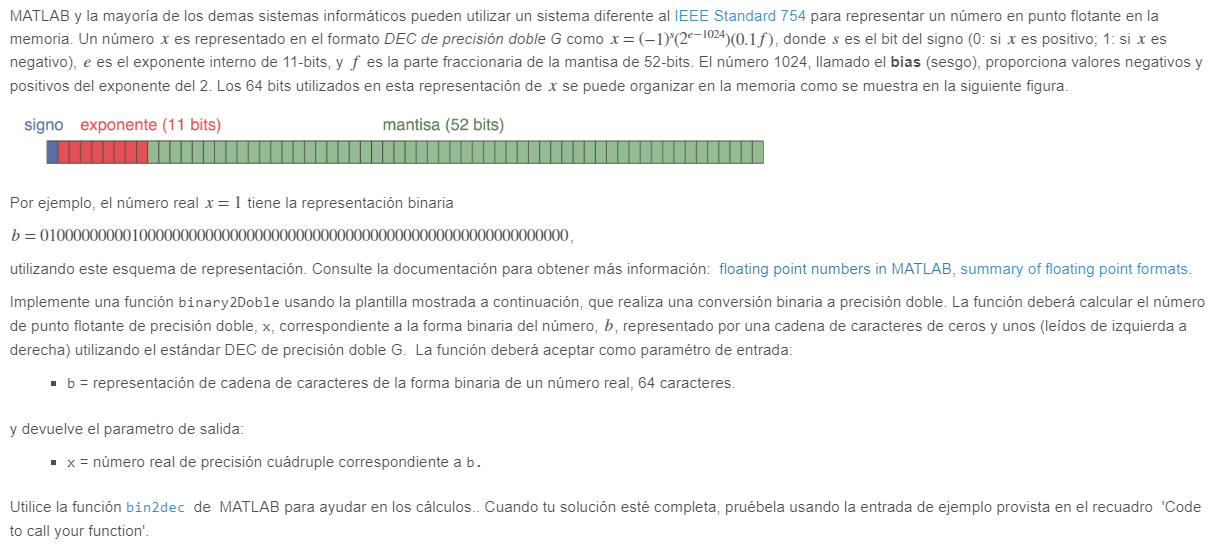

b ='1100000000001000000000000000000000000000000000000000000000000000';
x = binary2Double(b)

x =     -3


function [x] = binary2Double(b)
    s = bin2dec(b(1));
    e = bin2dec(b(2:12));
    m = b(13:64);

    E = e - 1023;
    M = bin2dec(m) / 2^-52;

    x = (-1)^s * (2^E) * (1 + M);
end